# Mask-based analysis

Zizhuang Miao

This script contains two examples of comparing neural correlates within pre-defined brain masks.

#### I. Brain-mask-based comparison of ToM engagement and demands

By comparing ToM engagement with ToM demands, we would like to explore the specificity of ToM engagment ratings in revealing ToM-related neural activity.

- Read data

% ...

% standardize betas in the whole brain
beta_text_med_sc = tomText_med.dat ./ mean(abs(tomText_med.dat));

----------------------------------------------
Study Info
----------------------------------------------
Primary_publication
Fill in this JSON-format file and call it study_info.json, in your main
study folder. This field would contain the primary publication associated
with the study, if any, or null if none.
 
Notes
This dataset was collected under the Spatial Topology project
 
Paradigm_files_links
https://github.com/spatialtopology/projects_narratives/tree/main/paradigms
 
Scanner_site
Dartmouth College
 
Field_strength
3.0T
 
Citing_this_work
If you use this dataset in a publication, 
please include as authors or acknowledge individuals as specified below. 
Please also see information on publications and grants to cite.
 
Authors_to_include_on_reuse
Zizhuang Miao, Heejung jung, Tor Wager
 
Authors_to_acknowledge_on_reuse
Tor Wager, Heejung jung
 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\canlabSecondLevel\tom_continuous_median
Loaded DAT from results\ima

----------------------------------------------
Study Info
----------------------------------------------
Info file study_info.json is missing.
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\canlabSecondLevel\tom_consensus
Loaded DAT from results\image_names_and_setup.mat
Loaded condition data from results\DATA_OBJ
Loaded condition data from results\DATA_OBJsc
Loaded contrast images from results\DATA_OBJ_CON
----------------------------------------------
Summary of dataset
----------------------------------------------
T_Gray_White_CSF reports T-values for whole-brain activation/deactivation in average gray matter, white matter, CSF
 
            Conditions            N_images    Condition_colors          T_Gray_White_CSF     
    __________________________    ________    _________________    __________________________

    {'ToM d

beta_audio_med_sc = tomAudio_med.dat ./ mean(abs(tomAudio_med.dat));
beta_text_cons_sc = tomText_cons.dat ./ mean(abs(tomText_cons.dat));
beta_audio_cons_sc = tomAudio_cons.dat ./ mean(abs(tomAudio_cons.dat));

2a. Define brain masks: Neurosynth term maps of "theory mind", "v1", "primary auditory", and "m1"

% load maps
mapDir = 'C:\'

tomMap = fmri_data([mapDir, 'theory mind_association-test_z_FDR_0.01.nii.gz']);
v1Map = fmri_data([mapDir, 'v1_association-test_z_FDR_0.01.nii.gz']);

mapDir = 'C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_nlp\results_ToM\neurosynthMaps\'

a1Map = fmri_data([mapDir, 'primary auditory_association-test_z_FDR_0.01.nii.gz']);
m1Map = fmri_data([mapDir, 'm1_association-test_z_FDR_0.01.nii.gz']);

Using default mask: C:\ResearchSoftwares\CANLabTools\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 0.031767 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 3600  Bit rate: 11.81 bits


Using default mask: C:\ResearchSoftwares\CANLabTools\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 0.017066 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 2159  Bit rate: 11.08 bits


tomMap_r = resample_space(tomMap, tomAudio_cons);

Using default mask: C:\ResearchSoftwares\CANLabTools\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 0.014420 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 2596  Bit rate: 11.34 bits


v1Map_r = resample_space(v1Map, tomAudio_cons);

Using default mask: C:\ResearchSoftwares\CANLabTools\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 0.013330 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 3655  Bit rate: 11.84 bits


a1Map_r = resample_space(a1Map, tomAudio_cons);
m1Map_r = resample_space(m1Map, tomAudio_cons);

% define masks by indices of voxels
indx = ~tomAudio_cons.removed_voxels;   % where there are data in the t maps
tomMasks = tomMap_r.dat(indx) > 0;
v1Masks = v1Map_r.dat(indx) > 0;
a1Masks = a1Map_r.dat(indx) > 0;
m1Masks = m1Map_r.dat(indx) > 0;    % the lowest z values in those maps are between 3 and 4

masks = {'tom', 'v1', 'a1', 'm1'};

3a. Extract and compare mean betas within masks

% extract means
for i = 1:4
    eval(['mean_text_med_' masks{i} ' = mean(beta_text_med_sc(' masks{i} 'Masks, :));'])
    eval(['mean_audio_med_' masks{i} ' = mean(beta_audio_med_sc(' masks{i} 'Masks, :));'])
    eval(['mean_text_cons_' masks{i} ' = mean(beta_text_cons_sc(' masks{i} 'Masks, :));'])
    eval(['mean_audio_cons_' masks{i} ' = mean(beta_audio_cons_sc(' masks{i} 'Masks, :));'])
end

% paired-sample t-tests
for i = 1:4
    disp(['Masks: ' masks{i}])
    disp('Text')
    eval(['[~, p, ~, stats] = ttest(mean_text_med_' masks{i} ', mean_text_cons_' masks{i} ')'])
    disp('Audio')
    eval(['[~, p, ~, stats] = ttest(mean_audio_med_' masks{i} ', mean_audio_cons_' masks{i} ')'])
end

Masks: tom


Text


p = single
4.2856e-05

stats = struct with fields:
    tstat: 4.3049
       df: 89
       sd: 0.7060


Audio


p = single
0

stats = struct with fields:
    tstat: 12.2605
       df: 89
       sd: 0.6942


Masks: v1


Text


p = single
0.0160

stats = struct with fields:
    tstat: -2.4557
       df: 89
       sd: 0.8634


Audio


p = single
0.6396

stats = struct with fields:
    tstat: 0.4699
       df: 89
       sd: 1.0143


Masks: a1


Text


p = single
0

stats = struct with fields:
    tstat: -14.5098
       df: 89
       sd: 0.7534


Audio


p = single
0

stats = struct with fields:
    tstat: 20.5630
       df: 89
       sd: 0.9210


Masks: m1


Text


p = single
1.4901e-06

stats = struct with fields:
    tstat: 5.1642
       df: 89
       sd: 0.6754


Audio


p = single
0.0038

stats = struct with fields:
    tstat: 2.9732
       df: 89
       sd: 0.7778


4a. Extract and compare correlations

disp('---------------------------')

---------------------------


disp('Compare correlations')

Compare correlations


for i = 1:4
    eval([masks{i} 'Map_data = ' masks{i} 'Map_r.dat(indx);'])
    eval(['cor_text_med_' masks{i} ' = corr(beta_text_med_sc(' masks{i} 'Masks, :), ' masks{i} 'Map_data(' masks{i} 'Masks));'])
    eval(['cor_text_cons_' masks{i} ' = corr(beta_text_cons_sc(' masks{i} 'Masks, :), ' masks{i} 'Map_data(' masks{i} 'Masks));'])
    eval(['z_text_med_' masks{i} ' = log((1+cor_text_med_' masks{i} ')./(1-cor_text_med_' masks{i} '))./2;'])
    eval(['z_text_cons_' masks{i} ' = log((1+cor_text_cons_' masks{i} ')./(1-cor_text_cons_' masks{i} '))./2;'])
    disp(['Masks: ' masks{i}])
    disp('Text')
    eval(['[~, p, ~, stats] = ttest(z_text_med_' masks{i} ', z_text_cons_' masks{i} ')'])
    
    eval(['cor_audio_med_' masks{i} ' = corr(beta_audio_med_sc(' masks{i} 'Masks, :), ' masks{i} 'Map_data(' masks{i} 'Masks));'])
    eval(['cor_audio_cons_' masks{i} ' = corr(beta_audio_cons_sc(' masks{i} 'Masks, :), ' masks{i} 'Map_data(' masks{i} 'Masks));'])
    eval(['z_audio_med_' masks{i} ' = log((1+cor_audio_med_' masks{i} ')./(1-cor_audio_med_' masks{i} '))./2;'])
    eval(['z_audio_cons_' masks{i} ' = log((1+cor_audio_cons_' masks{i} ')./(1-cor_audio_cons_' masks{i} '))./2;'])
    disp(['Masks: ' masks{i}])
    disp('Audio')
    eval(['[~, p, ~, stats] = ttest(z_audio_med_' masks{i} ', z_audio_cons_' masks{i} ')'])
end

Masks: tom


Text


p = single
0

stats = struct with fields:
    tstat: 9.7373
       df: 89
       sd: 0.1139


Masks: tom


Audio


p = single
0

stats = struct with fields:
    tstat: 13.8704
       df: 89
       sd: 0.1290


Masks: v1


Text


p = single
0.3676

stats = struct with fields:
    tstat: -0.9055
       df: 89
       sd: 0.1692


Masks: v1


Audio


p = single
0.2382

stats = struct with fields:
    tstat: 1.1874
       df: 89
       sd: 0.1661


Masks: a1


Text


p = single
0

stats = struct with fields:
    tstat: -18.9154
       df: 89
       sd: 0.1614


Masks: a1


Audio


p = single
0

stats = struct with fields:
    tstat: 18.0613
       df: 89
       sd: 0.1961


Masks: m1


Text


p = single
0

stats = struct with fields:
    tstat: 7.3237
       df: 89
       sd: 0.1372


Masks: m1


Audio


p = single
0

stats = struct with fields:
    tstat: 11.3498
       df: 89
       sd: 0.1229


2b. Define brain masks using CANlab 2024 atlas -- some regions supposedly not related to ToM

% load the coarse 2mm atlas
canlab2024 = load_atlas('canlab2024');

Loading atlas: CANLab2023_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat


canlab2024_thr = canlab2024.threshold(0.2);

Keeping probability_map values above 0.20


canlab2024_thr = resample_space(canlab2024_thr, tomAudio_med);

Some atlas regions lost in resampling:
   478   479



% match the space of resampled atlas and the original atlas
if size(canlab2024_thr.probability_maps, 2) < size(canlab2024_thr.labels, 2)
    diff = size(canlab2024_thr.labels, 2) - size(canlab2024_thr.probability_maps, 2);
    for i = 1:diff
        canlab2024_thr.probability_maps = ...
            [canlab2024_thr.probability_maps, zeros(size(canlab2024_thr.probability_maps, 1), 1)];
    end
end

% select regions of interest
v1 = select_atlas_subset(canlab2024_thr, {'striate_L', 'striate_R'}, ...
    'flatten', 'labels_2', 'exact').dat(~tomAudio_med.removed_voxels);
vEarly = select_atlas_subset(canlab2024_thr, {'visual_early'}, ...
    'flatten', 'labels_3').dat(~tomAudio_med.removed_voxels);
m1 = select_atlas_subset(canlab2024_thr, {'M1_'}, ...
    'flatten', 'labels_2').dat(~tomAudio_med.removed_voxels);
a1 = select_atlas_subset(canlab2024_thr, {'A1_'}, ...
    'flatten', 'labels_2').dat(~tomAudio_med.removed_voxels);
posIns = select_atlas_subset(canlab2024_thr, {'posterior_granular_insula'}, ...
    'flatten', 'labels_2').dat(~tomAudio_med.removed_voxels);
infIns = select_atlas_subset(canlab2024_thr, {'inferior_dysgranular_insula'}, ...
    'flatten', 'labels_2').dat(~tomAudio_med.removed_voxels);
antIns = select_atlas_subset(canlab2024_thr, {'anterior_agranular_insula'}, ...
    'flatten', 'labels_2').dat(~tomAudio_med.removed_voxels);
hippo = select_atlas_subset(canlab2024_thr, {'hippocampal_formation'}, ...
    'flatten', 'labels_2').dat(~tomAudio_med.removed_voxels);

masks = {'v1', 'vEarly', 'a1', 'm1', 'posIns', 'infIns', 'antIns', 'hippo'};

3b. Extract and compare mean betas within masks

% extract means
for i = 1:8
    eval(['mean_text_med_' masks{i} ' = mean(beta_text_med_sc(logical(' masks{i} '), :));'])
    eval(['mean_audio_med_' masks{i} ' = mean(beta_audio_med_sc(logical(' masks{i} '), :));'])
    eval(['mean_text_cons_' masks{i} ' = mean(beta_text_cons_sc(logical(' masks{i} '), :));'])
    eval(['mean_audio_cons_' masks{i} ' = mean(beta_audio_cons_sc(logical(' masks{i} '), :));'])
end

% paired-sample t-tests
for i = 1:8
    disp(['Masks: ' masks{i}])
    disp('Text')
    eval(['[~, p, ~, stats] = ttest(mean_text_med_' masks{i} ', mean_text_cons_' masks{i} ')'])
    disp('Audio')
    eval(['[~, p, ~, stats] = ttest(mean_audio_med_' masks{i} ', mean_audio_cons_' masks{i} ')'])
end

Masks: v1


Text


p = single
0.0230

stats = struct with fields:
    tstat: -2.3134
       df: 89
       sd: 1.1492


Audio


p = single
0.7143

stats = struct with fields:
    tstat: 0.3672
       df: 89
       sd: 1.2859


Masks: vEarly


Text


p = single
0.0069

stats = struct with fields:
    tstat: -2.7651
       df: 89
       sd: 0.9564


Audio


p = single
0.6089

stats = struct with fields:
    tstat: 0.5135
       df: 89
       sd: 1.1232


Masks: a1


Text


p = single
0

stats = struct with fields:
    tstat: -12.5092
       df: 89
       sd: 1.0813


Audio


p = single
0

stats = struct with fields:
    tstat: 18.3940
       df: 89
       sd: 1.1933


Masks: m1


Text


p = single
5.5128e-04

stats = struct with fields:
    tstat: 3.5842
       df: 89
       sd: 0.7492


Audio


p = single
0.0618

stats = struct with fields:
    tstat: 1.8912
       df: 89
       sd: 0.8641


Masks: posIns


Text


p = single
5.3728e-04

stats = struct with fields:
    tstat: -3.5919
       df: 89
       sd: 0.7491


Audio


p = single
0.0055

stats = struct with fields:
    tstat: 2.8451
       df: 89
       sd: 0.8635


Masks: infIns


Text


p = single
4.7415e-04

stats = struct with fields:
    tstat: -3.6292
       df: 89
       sd: 0.6720


Audio


p = single
0.1110

stats = struct with fields:
    tstat: -1.6095
       df: 89
       sd: 0.8945


Masks: antIns


Text


p = single
0.3331

stats = struct with fields:
    tstat: 0.9732
       df: 89
       sd: 0.7300


Audio


p = single
0.2531

stats = struct with fields:
    tstat: -1.1503
       df: 89
       sd: 0.9592


Masks: hippo


Text


p = single
0.7638

stats = struct with fields:
    tstat: -0.3014
       df: 89
       sd: 0.6172


Audio


p = single
0

stats = struct with fields:
    tstat: 8.0823
       df: 89
       sd: 0.5961


4b. Plot the results

names = {'V1', 'V1-4', 'A1', 'M1', 'Posterior insula', 'Inferior insula', ... 
    'Anterior insula', 'Hippocampus'}

names = 1×8 cell array
    {'V1'}    {'V1-4'}    {'A1'}    {'M1'}    {'Posterior insula'}    {'Inferior insula'}    {'Anterior insula'}    {'Hippocampus'}


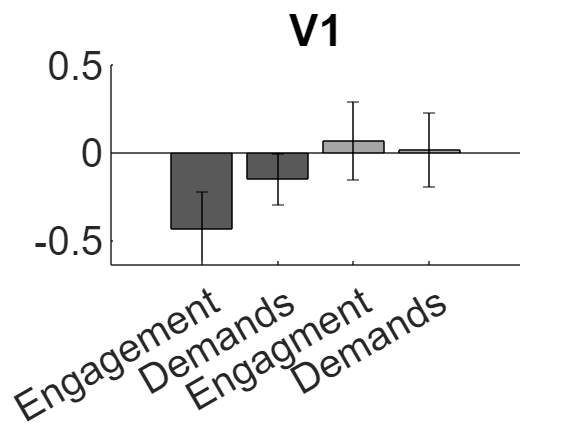

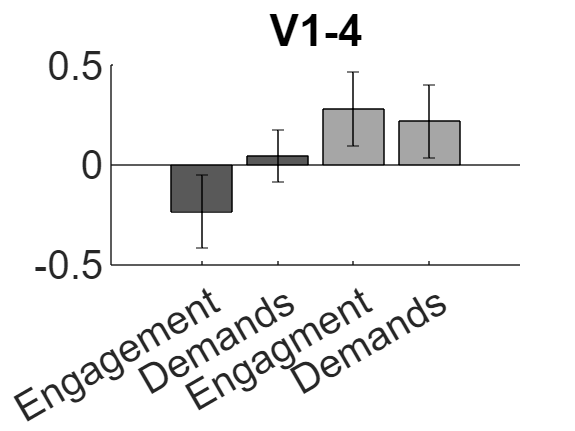

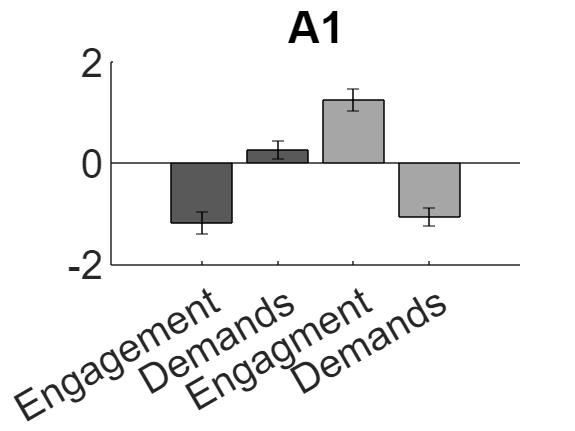

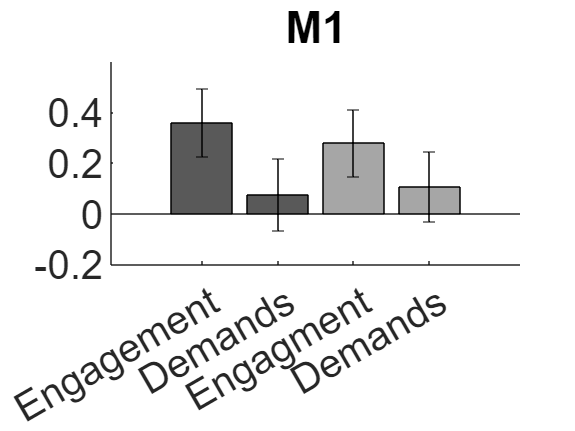

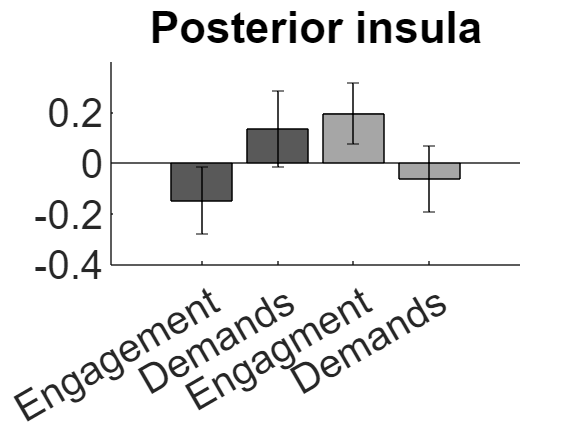

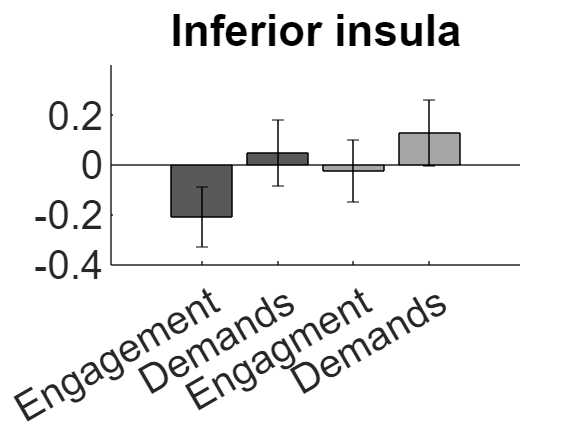

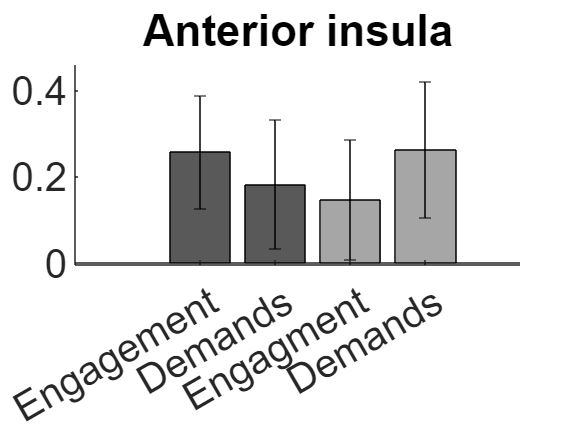

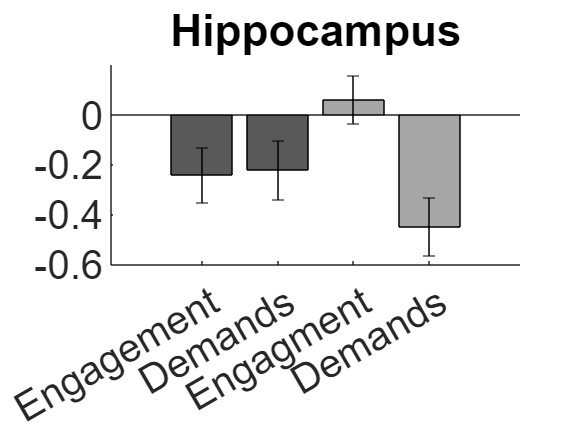


for i = 1:size(masks,2)
    eval(['allmeans_' masks{i} ' = [mean(mean_text_med_' masks{i} ...
        '), mean(mean_text_cons_' masks{i} '), mean(mean_audio_med_' ...
        masks{i} '), mean(mean_audio_cons_' masks{i} ')];'])
    eval(['allcis_' masks{i} ' = 1.96*[std(mean_text_med_' ...
        masks{i} '), std(mean_text_cons_' masks{i} ...
        '), std(mean_audio_med_' masks{i} '), std(mean_audio_cons_' ...
        masks{i} ')]./sqrt(90);'])
    
    figure;
    eval(['b = bar(allmeans_' masks{i} ');'])
    hold on;
    ax = gca;
    set(ax, 'box', 'off', 'color', 'none');
    
    b.FaceColor = 'flat';
    b.CData = [0.35 0.35 0.35; 0.35 0.35 0.35;
               0.65 0.65 0.65; 0.65 0.65 0.65];    % specify the color of each bar
    
    numBars = 4;
    eval(['errorbar(1:numBars, allmeans_' masks{i} ', allcis_' masks{i} ...
        ', "k", "LineStyle", "none");'])
    
    hold off;
    
    xticklabels({'Engagement', 'Demands', ...
    'Engagment', 'Demands'});
    title(names{i})
    set(gca, 'FontSize', 20)
    ylabel('');
end

#### II. Brain-mask-based Bayes Factor analysis

In this section, I will focus on regions that respond to both social interactions and ToM or only one of them. The way to do this is extracting average individual betas from each region, calculating and displaying the standardized effect size. Then we calculate one t value for one region*modality pair and translate the t values will be into Bayes Factors shown on a graph.

% read data
% ...

**a. Regions that respond to both**

Candidates include (in canlab2024 atlas):

- bilateral PC: 'precuneus_L' and 'precuneus_R' in 'labels_2' (exact match)

- left TPJ: 'PGi_L' and 'PGs_L' in 'labels'

- dmPFC: 'dmPFC' in 'labels_2'

- left STS: 'STS*_L' in 'labels' and 'TPOJ1_L', 'TPOJ2_L' in 'labels'

- MTG: 'middle_temporal_gyrus' in 'labels_2'

- IFG: 'BA44' and 'BA45' in 'labels_2

% load and resample atlas
canlab2024 = load_atlas('canlab2024');

----------------------------------------------
Study Info
----------------------------------------------
Primary_publication
Fill in this JSON-format file and call it study_info.json, in your main
study folder. This field would contain the primary publication associated
with the study, if any, or null if none.
 
Notes
This dataset was collected under the Spatial Topology project
 
Paradigm_files_links
https://github.com/spatialtopology/projects_narratives/tree/main/paradigms
 
Scanner_site
Dartmouth College
 
Field_strength
3.0T
 
Citing_this_work
If you use this dataset in a publication, 
please include as authors or acknowledge individuals as specified below. 
Please also see information on publications and grants to cite.
 
Authors_to_include_on_reuse
Zizhuang Miao, Heejung jung, Tor Wager
 
Authors_to_acknowledge_on_reuse
Tor Wager, Heejung jung
 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\canlabSecondLevel\tom_social_continuous
Loaded DAT from results\ima

canlab2024_thr = canlab2024.threshold(0.2);
canlab2024_thr = resample_space(canlab2024_thr, sintText);

% match the space of resampled atlas and the original atlas by adding two
% columns to probability maps corresponding to the lost regions
canlab2024_thr.probability_maps = ...

Loading atlas: CANLab2023_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat


            [canlab2024_thr.probability_maps(:, 1:477), ...

Keeping probability_map values above 0.20


            zeros(size(canlab2024_thr.probability_maps, 1), 2), ...

Some atlas regions lost in resampling:
   478   479



            canlab2024_thr.probability_maps(:, 478:end)];

% select regions of interest
prec = select_atlas_subset(canlab2024_thr, {'precuneus_L', 'precuneus_R'}, ...
    'flatten', 'labels_2', 'exact').dat(~sintText.removed_voxels);
ltpj = select_atlas_subset(canlab2024_thr, {'PGi_L', 'PGs_L'}, ...
    'flatten', 'labels').dat(~sintText.removed_voxels);
dmPFC = select_atlas_subset(canlab2024_thr, {'dmPFC'}, ...
    'flatten', 'labels_2').dat(~sintText.removed_voxels);
sts1 = select_atlas_subset(canlab2024_thr, {'STSda_L', 'STSdp_L', 'STSva_L', 'STSvp_L'}, ...
    'flatten', 'labels').dat(~sintText.removed_voxels);
sts2 = select_atlas_subset(canlab2024_thr, {'TPOJ1_L', 'TPOJ2_L'}, ...
    'flatten', 'labels').dat(~sintText.removed_voxels);
lsts = single(sts1==1 | sts2==1);
mtg = select_atlas_subset(canlab2024_thr, {'middle_temporal_gyrus'}, ...
    'flatten', 'labels_2').dat(~sintText.removed_voxels);
ifg = select_atlas_subset(canlab2024_thr, {'BA44', 'BA45'}, ...
    'flatten', 'labels_2').dat(~sintText.removed_voxels);

masks = {'prec', 'ltpj', 'dmPFC', 'lsts', 'mtg', 'ifg'};

% calculate t values for each region*modality pair
for i = 1:6
    eval(['mean_sint_text_' masks{i} ' = mean(sintText.dat(logical(' masks{i} '), :));'])
    eval(['mean_sint_audio_' masks{i} ' = mean(sintAudio.dat(logical(' masks{i} '), :));'])
    eval(['mean_tom_text_' masks{i} ' = mean(tomText.dat(logical(' masks{i} '), :));'])
    eval(['mean_tom_audio_' masks{i} ' = mean(tomAudio.dat(logical(' masks{i} '), :));'])

    eval(['[~, p, ~, stat_sint_text_' masks{i} '] = ttest(mean_sint_text_' masks{i} ')'])
    eval(['[~, p, ~, stat_sint_audio_' masks{i} '] = ttest(mean_sint_audio_' masks{i} ')'])
    eval(['[~, p, ~, stat_tom_text_' masks{i} '] = ttest(mean_tom_text_' masks{i} ')'])
    eval(['[~, p, ~, stat_tom_audio_' masks{i} '] = ttest(mean_tom_audio_' masks{i} ')'])
end

p = single
1.4901e-06

stat_sint_text_prec = struct with fields:
    tstat: 5.1549
       df: 89
       sd: 0.0742


p = single
0.0121

stat_sint_audio_prec = struct with fields:
    tstat: 2.5627
       df: 89
       sd: 0.0682


p = single
0

stat_tom_text_prec = struct with fields:
    tstat: 9.0761
       df: 89
       sd: 0.1740


p = single
0

stat_tom_audio_prec = struct with fields:
    tstat: 9.3156
       df: 89
       sd: 0.1918


p = single
0

stat_sint_text_ltpj = struct with fields:
    tstat: 6.5353
       df: 89
       sd: 0.0638


p = single
7.6056e-05

stat_sint_audio_ltpj = struct with fields:
    tstat: 4.1496
       df: 89
       sd: 0.0638


p = single
0

stat_tom_text_ltpj = struct with fields:
    tstat: 8.3518
       df: 89
       sd: 0.1749


p = single
0

stat_tom_audio_ltpj = struct with fields:
    tstat: 9.8373
       df: 89
       sd: 0.1896


p = single
2.3842e-07

stat_sint_text_dmPFC = struct with fields:
    tstat: 5.6260
       df: 89
       sd: 0.0580


p = single
0

stat_sint_audio_dmPFC = struct with fields:
    tstat: 6.2112
       df: 89
       sd: 0.0668


p = single
0

stat_tom_text_dmPFC = struct with fields:
    tstat: 6.3762
       df: 89
       sd: 0.1875


p = single
0

stat_tom_audio_dmPFC = struct with fields:
    tstat: 7.2949
       df: 89
       sd: 0.1876


p = single
0

stat_sint_text_lsts = struct with fields:
    tstat: 8.0844
       df: 89
       sd: 0.0618


p = single
0

stat_sint_audio_lsts = struct with fields:
    tstat: 6.2136
       df: 89
       sd: 0.0688


p = single
0

stat_tom_text_lsts = struct with fields:
    tstat: 7.2711
       df: 89
       sd: 0.1819


p = single
0

stat_tom_audio_lsts = struct with fields:
    tstat: 14.2815
       df: 89
       sd: 0.2099


p = single
0.1240

stat_sint_text_mtg = struct with fields:
    tstat: 1.5530
       df: 89
       sd: 0.0436


p = single
0.6599

stat_sint_audio_mtg = struct with fields:
    tstat: -0.4416
       df: 89
       sd: 0.0462


p = single
0.2050

stat_tom_text_mtg = struct with fields:
    tstat: 1.2768
       df: 89
       sd: 0.1354


p = single
1.1444e-04

stat_tom_audio_mtg = struct with fields:
    tstat: 4.0369
       df: 89
       sd: 0.1240


p = single
3.0041e-05

stat_sint_text_ifg = struct with fields:
    tstat: 4.3995
       df: 89
       sd: 0.0523


p = single
0

stat_sint_audio_ifg = struct with fields:
    tstat: 6.4516
       df: 89
       sd: 0.0595


p = single
0

stat_tom_text_ifg = struct with fields:
    tstat: 6.6267
       df: 89
       sd: 0.1768


p = single
0

stat_tom_audio_ifg = struct with fields:
    tstat: 8.1094
       df: 89
       sd: 0.1766


The "process*modality*region" pairs that are not significant are as follows: _mtg except tom_audio_mtg

% translate t values into bayes factors -- only do the consistent ones
masks_revised = {'prec', 'ltpj', 'dmPFC', 'lsts', 'ifg'};

for i = 1:5
   eval(['bf_sint_text_' masks_revised{i} '= t1smpbf(stat_sint_text_' ...
       masks_revised{i} '.tstat, stat_sint_text_' masks_revised{i} '.df+1);'])
   eval(['bf_sint_audio_' masks_revised{i} '= t1smpbf(stat_sint_audio_' ...
       masks_revised{i} '.tstat, stat_sint_audio_' masks_revised{i} '.df+1);'])
   eval(['bf_tom_text_' masks_revised{i} '= t1smpbf(stat_tom_text_' ...
       masks_revised{i} '.tstat, stat_tom_text_' masks_revised{i} '.df+1);'])
   eval(['bf_tom_audio_' masks_revised{i} '= t1smpbf(stat_tom_audio_' ...
       masks_revised{i} '.tstat, stat_tom_audio_' masks_revised{i} '.df+1);'])
end

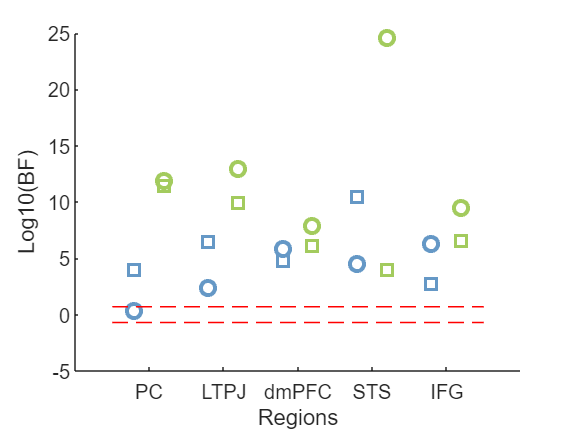

% plot Bayes Factors
figure;
hold on;

processes = {'sint', 'tom'};
modalities = {'text', 'audio'};

% define colors for different processes and markers for different modalities
colors = [101, 152, 198; 163, 203, 94] ./ 255; % sint and tom
markers = ['s', 'o']; % square for text, circle for audio

% Plot the data
for r = 1:5
    for p = 1:2
        for m = 1:2
            % calculate x positions for plotting
            x = r-0.2 + (p-1)*0.4; % Slight offset for processes
            eval(['y = log10(bf_' processes{p} '_' modalities{m} ...
                '_' masks_revised{r} ');'])
            scatter(x, y, 50, colors(p, :), markers(m), 'LineWidth', 2);
        end
    end
end

hline([log10(5), log10(1/5)], {'r--', 'r--'})
xlabel('Regions');
ylabel('Log10(BF)');
xticks(1:5)
xticklabels({'PC', 'LTPJ', 'dmPFC', 'STS', 'IFG'})
hold off;

**b. Regions that respond to ToM only**

Candidates include (all in 'labels_2):

- 'premotor_R'

- 'SMA'

- 'anterior_IPL'

- 'vMT+'

and in 'labels': left TPJ, 'PGi' and 'PGs' in 'labels'

% load and resample atlas
canlab2024 = load_atlas('canlab2024');

Loading atlas: CANLab2023_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat


canlab2024_thr = canlab2024.threshold(0.2);

Keeping probability_map values above 0.20


canlab2024_thr = resample_space(canlab2024_thr, sintText);

Some atlas regions lost in resampling:
   478   479




% add the lost regions as 0 columns
canlab2024_thr.probability_maps = ...
            [canlab2024_thr.probability_maps(:, 1:477), ...
            zeros(size(canlab2024_thr.probability_maps, 1), 2), ...
            canlab2024_thr.probability_maps(:, 478:end)];

% select regions of interest
rpremotor = select_atlas_subset(canlab2024_thr, {'premotor_R'}, ...
    'flatten', 'labels_2').dat(~sintText.removed_voxels);
sma = select_atlas_subset(canlab2024_thr, {'SMA'}, ...
    'flatten', 'labels_2').dat(~sintText.removed_voxels);
aipl = select_atlas_subset(canlab2024_thr, {'anterior_IPL'}, ...
    'flatten', 'labels_2').dat(~sintText.removed_voxels);
mtplus = select_atlas_subset(canlab2024_thr, {'vMT+'}, ...
    'flatten', 'labels_2').dat(~sintText.removed_voxels);
rtpj = select_atlas_subset(canlab2024_thr, {'PGi_R', 'PGs_R'}, ...
    'flatten', 'labels').dat(~sintText.removed_voxels);

masks = {'rpremotor', 'sma', 'aipl', 'mtplus', 'rtpj'};

% calculate t values for each region*modality pair
for i = 1:5
    eval(['mean_sint_text_' masks{i} ' = mean(sintText.dat(logical(' masks{i} '), :));'])
    eval(['mean_sint_audio_' masks{i} ' = mean(sintAudio.dat(logical(' masks{i} '), :));'])
    eval(['mean_tom_text_' masks{i} ' = mean(tomText.dat(logical(' masks{i} '), :));'])
    eval(['mean_tom_audio_' masks{i} ' = mean(tomAudio.dat(logical(' masks{i} '), :));'])

    eval(['[~, p, ~, stat_sint_text_' masks{i} '] = ttest(mean_sint_text_' masks{i} ')'])
    eval(['[~, p, ~, stat_sint_audio_' masks{i} '] = ttest(mean_sint_audio_' masks{i} ')'])
    eval(['[~, p, ~, stat_tom_text_' masks{i} '] = ttest(mean_tom_text_' masks{i} ')'])
    eval(['[~, p, ~, stat_tom_audio_' masks{i} '] = ttest(mean_tom_audio_' masks{i} ')'])
end

p = single
0.9509

stat_sint_text_rpremotor = struct with fields:
    tstat: 0.0618
       df: 89
       sd: 0.0442


p = single
0.5599

stat_sint_audio_rpremotor = struct with fields:
    tstat: 0.5852
       df: 89
       sd: 0.0564


p = single
0

stat_tom_text_rpremotor = struct with fields:
    tstat: 6.4609
       df: 89
       sd: 0.1523


p = single
5.9605e-08

stat_tom_audio_rpremotor = struct with fields:
    tstat: 5.9562
       df: 89
       sd: 0.1446


p = single
0.6550

stat_sint_text_sma = struct with fields:
    tstat: -0.4484
       df: 89
       sd: 0.0476


p = single
0.1335

stat_sint_audio_sma = struct with fields:
    tstat: 1.5143
       df: 89
       sd: 0.0534


p = single
0

stat_tom_text_sma = struct with fields:
    tstat: 9.1051
       df: 89
       sd: 0.1469


p = single
0

stat_tom_audio_sma = struct with fields:
    tstat: 9.1178
       df: 89
       sd: 0.1359


p = single
0.4128

stat_sint_text_aipl = struct with fields:
    tstat: -0.8228
       df: 89
       sd: 0.0502


p = single
0.0016

stat_sint_audio_aipl = struct with fields:
    tstat: -3.2616
       df: 89
       sd: 0.0640


p = single
5.8246e-04

stat_tom_text_aipl = struct with fields:
    tstat: 3.5678
       df: 89
       sd: 0.1556


p = single
0.0113

stat_tom_audio_aipl = struct with fields:
    tstat: 2.5869
       df: 89
       sd: 0.1517


p = single
0.7063

stat_sint_text_mtplus = struct with fields:
    tstat: 0.3781
       df: 89
       sd: 0.0498


p = single
0.4832

stat_sint_audio_mtplus = struct with fields:
    tstat: 0.7042
       df: 89
       sd: 0.0789


p = single
0

stat_tom_text_mtplus = struct with fields:
    tstat: 6.1489
       df: 89
       sd: 0.1624


p = single
0

stat_tom_audio_mtplus = struct with fields:
    tstat: 6.4469
       df: 89
       sd: 0.1945


p = single
0.0021

stat_sint_text_rtpj = struct with fields:
    tstat: 3.1743
       df: 89
       sd: 0.0589


p = single
0.8780

stat_sint_audio_rtpj = struct with fields:
    tstat: -0.1540
       df: 89
       sd: 0.0681


p = single
0

stat_tom_text_rtpj = struct with fields:
    tstat: 7.2403
       df: 89
       sd: 0.1548


p = single
0

stat_tom_audio_rtpj = struct with fields:
    tstat: 7.8235
       df: 89
       sd: 0.1788



% translate t values into bayes factors -- only do the consistent ones
for i = 1:5
   eval(['bf_sint_text_' masks{i} '= t1smpbf(stat_sint_text_' ...
       masks{i} '.tstat, stat_sint_text_' masks{i} '.df+1);'])
   eval(['bf_sint_audio_' masks{i} '= t1smpbf(stat_sint_audio_' ...
       masks{i} '.tstat, stat_sint_audio_' masks{i} '.df+1);'])
   eval(['bf_tom_text_' masks{i} '= t1smpbf(stat_tom_text_' ...
       masks{i} '.tstat, stat_tom_text_' masks{i} '.df+1);'])
   eval(['bf_tom_audio_' masks{i} '= t1smpbf(stat_tom_audio_' ...
       masks{i} '.tstat, stat_tom_audio_' masks{i} '.df+1);'])
end

% plot Bayes Factors
figure;
hold on;

masks = {'prec', 'lsts', 'rtpj', 'sma'}

masks = 1×4 cell array
    {'prec'}    {'lsts'}    {'rtpj'}    {'sma'}


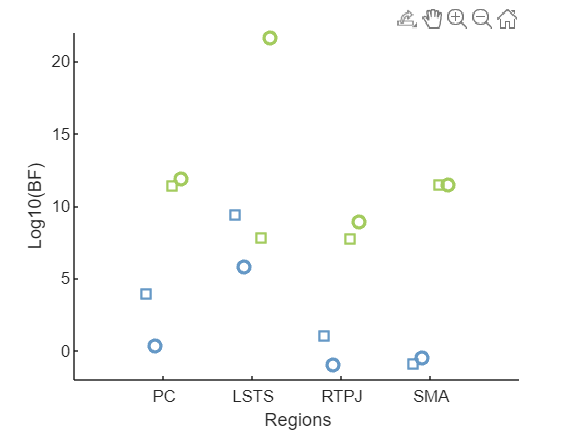

processes = {'sint', 'tom'};
modalities = {'text', 'audio'};

% define colors for different processes and markers for different modalities
colors = [101, 152, 198; 163, 203, 94] ./ 255; % sint and tom
markers = ['s', 'o']; % square for text, circle for audio

% Plot the data
for r = 1:4
    for p = 1:2
        for m = 1:2
            % calculate x positions for plotting
            x = r-0.2 + (p-1)*0.3 + (m-1)*0.1; % slight offset for processes and modalities
            eval(['y = log10(bf_' processes{p} '_' modalities{m} '_' masks{r} ');'])
            scatter(x, y, 50, colors(p, :), markers(m), 'LineWidth', 2);
        end
    end
end

xlabel('Regions');
ylabel('Log10(BF)');
ylim([-2, 22])
xticks(1:4)
xticklabels({'PC', 'LSTS', 'RTPJ', 'SMA'})
hold off;

**Plot standardized betas (effect size) for both common and ToM unique regions**

ma = {'prec', 'lsts', 'rtpj', 'sma'}

ma = 1×4 cell array
    {'prec'}    {'lsts'}    {'rtpj'}    {'sma'}


titles = {'PC', 'LSTS', 'RTPJ', 'SMA'}

titles = 1×4 cell array
    {'PC'}    {'LSTS'}    {'RTPJ'}    {'SMA'}


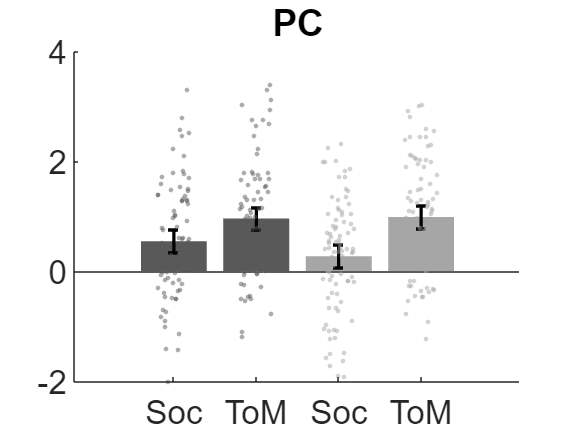

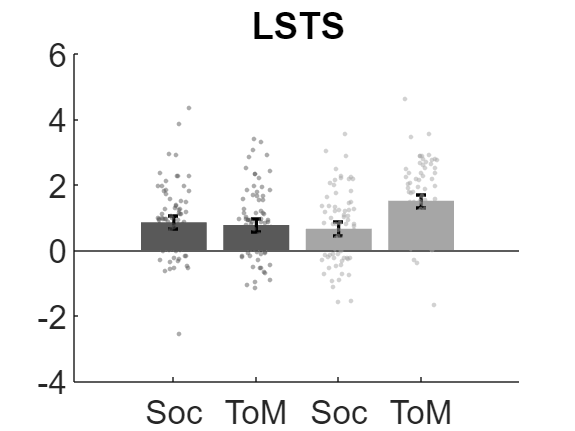

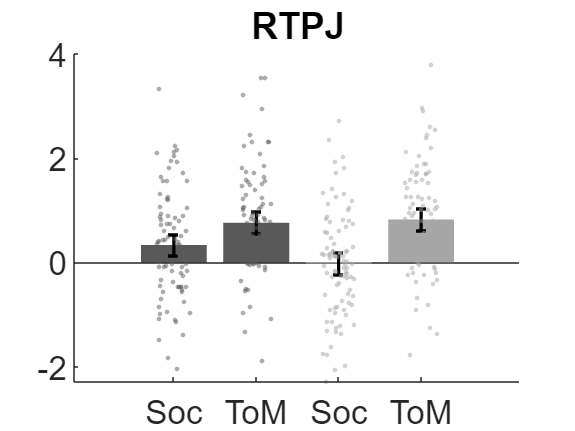

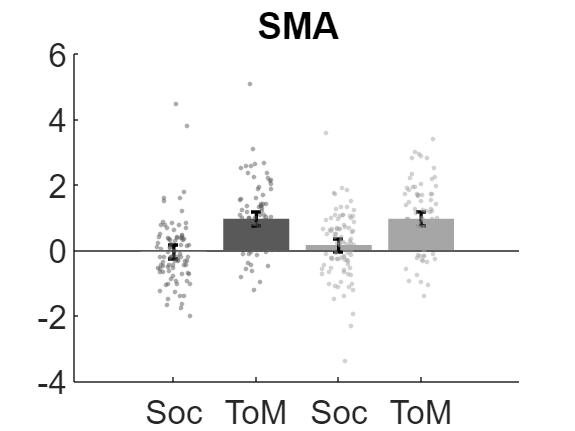

Writing: 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\mask_images\prec.nii
Writing: 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\mask_images\lsts.nii
Writing: 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\mask_images\rtpj.nii
Writing: 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\results_analysis\mask_images\sma.nii


----------------------------------------------
Study Info
----------------------------------------------
Info file study_info.json is missing.
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\canlabSecondLevel\social_continuous_median
Loaded DAT from results\image_names_and_setup.mat
Loaded condition data from results\DATA_OBJ
Loaded condition data from results\DATA_OBJsc
No contrast data objects to load.
----------------------------------------------
Summary of dataset
----------------------------------------------
T_Gray_White_CSF reports T-values for whole-brain activation/deactivation in average gray matter, white matter, CSF
 
          Conditions           N_images    Condition_colors            T_Gray_White_CSF       
    _______________________    ________    _________________    ______________________________

    {'SInt me

******************************************
Warning! Some p-values are zero.
FDR.m will interpret these as ineligible voxels.
If these are valid p-values, they should have some not-exactly-zero value.
******************************************



Image   1
 91 contig. clusters, sizes   1 to 15203
Positive effect: 44624 voxels, min p-value: 0.00000000
Negative effect: 12632 voxels, min p-value: 0.00000000



Image   1
 82 contig. clusters, sizes   1 to 40195
Positive effect: 55583 voxels, min p-value: 0.00000000
Negative effect: 17262 voxels, min p-value: 0.00000000


----------------------------------------------
Study Info
----------------------------------------------
Info file study_info.json is missing.
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\canlabSecondLevel\social_consensus
Loaded DAT from results\image_names_and_setup.mat
Loaded condition data from results\DATA_OBJ
Loaded condition data from results\DATA_OBJsc
Loaded contrast images from results\DATA_OBJ_CON
----------------------------------------------
Summary of dataset
----------------------------------------------
T_Gray_White_CSF reports T-values for whole-brain activation/deactivation in average gray matter, white matter, CSF
 
        Conditions        N_images    Condition_colors          T_Gray_White_CSF     
    __________________    ________    _________________    __________________________

    {'SInt (text)'   }  

******************************************
Warning! Some p-values are zero.
FDR.m will interpret these as ineligible voxels.
If these are valid p-values, they should have some not-exactly-zero value.
******************************************



Image   1
110 contig. clusters, sizes   1 to 7423
Positive effect: 19561 voxels, min p-value: 0.00000000
Negative effect: 18647 voxels, min p-value: 0.00000000



Image   1
 99 contig. clusters, sizes   1 to 13408
Positive effect: 34626 voxels, min p-value: 0.00000000
Negative effect: 12451 voxels, min p-value: 0.00000000


----------------------------------------------
Study Info
----------------------------------------------
Primary_publication
Fill in this JSON-format file and call it study_info.json, in your main
study folder. This field would contain the primary publication associated
with the study, if any, or null if none.
 
Notes
This dataset was collected under the Spatial Topology project
 
Paradigm_files_links
https://github.com/spatialtopology/projects_narratives/tree/main/paradigms
 
Scanner_site
Dartmouth College
 
Field_strength
3.0T
 
Citing_this_work
If you use this dataset in a publication, 
please include as authors or acknowledge individuals as specified below. 
Please also see information on publications and grants to cite.
 
Authors_to_include_on_reuse
Zizhuang Miao, Heejung jung, Tor Wager
 
Authors_to_acknowledge_on_reuse
Tor Wager, Heejung jung
 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\canlabSecondLevel\tom_continuous_median
Loaded DAT from results\ima

******************************************
Warning! Some p-values are zero.
FDR.m will interpret these as ineligible voxels.
If these are valid p-values, they should have some not-exactly-zero value.
******************************************



Image   1
 45 contig. clusters, sizes   1 to 112642
Positive effect: 86666 voxels, min p-value: 0.00000000
Negative effect: 31017 voxels, min p-value: 0.00000000



Image   1
 53 contig. clusters, sizes   1 to 109024
Positive effect: 83334 voxels, min p-value: 0.00000000
Negative effect: 28331 voxels, min p-value: 0.00000000


----------------------------------------------
Study Info
----------------------------------------------
Info file study_info.json is missing.
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\canlabSecondLevel\tom_consensus
Loaded DAT from results\image_names_and_setup.mat
Loaded condition data from results\DATA_OBJ
Loaded condition data from results\DATA_OBJsc
Loaded contrast images from results\DATA_OBJ_CON
----------------------------------------------
Summary of dataset
----------------------------------------------
T_Gray_White_CSF reports T-values for whole-brain activation/deactivation in average gray matter, white matter, CSF
 
            Conditions            N_images    Condition_colors          T_Gray_White_CSF     
    __________________________    ________    _________________    __________________________

    {'ToM d

******************************************
Warning! Some p-values are zero.
FDR.m will interpret these as ineligible voxels.
If these are valid p-values, they should have some not-exactly-zero value.
******************************************



Image   1
125 contig. clusters, sizes   1 to 15698
Positive effect: 32598 voxels, min p-value: 0.00000000
Negative effect: 7362 voxels, min p-value: 0.00000000



Image   1
 91 contig. clusters, sizes   1 to 34517
Positive effect: 40997 voxels, min p-value: 0.00000000
Negative effect: 14095 voxels, min p-value: 0.00000000


----------------------------------------------
Study Info
----------------------------------------------
Primary_publication
Fill in this JSON-format file and call it study_info.json, in your main
study folder. This field would contain the primary publication associated
with the study, if any, or null if none.
 
Notes
This dataset was collected under the Spatial Topology project
 
Paradigm_files_links
https://github.com/spatialtopology/projects_narratives/tree/main/paradigms
 
Scanner_site
Dartmouth College
 
Field_strength
3.0T
 
Citing_this_work
If you use this dataset in a publication, 
please include as authors or acknowledge individuals as specified below. 
Please also see information on publications and grants to cite.
 
Authors_to_include_on_reuse
Zizhuang Miao, Heejung jung, Tor Wager
 
Authors_to_acknowledge_on_reuse
Tor Wager, Heejung jung
 
C:\Users\f006fkn\Desktop\SpacetopNarrativesStudy\projects_comparison\canlabSecondLevel\tom_social_continuous
Loaded DAT from results\ima

******************************************
Warning! Some p-values are zero.
FDR.m will interpret these as ineligible voxels.
If these are valid p-values, they should have some not-exactly-zero value.
******************************************



Image   1
125 contig. clusters, sizes   1 to 23076
Positive effect: 41863 voxels, min p-value: 0.00000000
Negative effect: 19262 voxels, min p-value: 0.00000000



Image   1
107 contig. clusters, sizes   1 to 17305
Positive effect: 42329 voxels, min p-value: 0.00000000
Negative effect: 27014 voxels, min p-value: 0.00000000



Image   1
 44 contig. clusters, sizes   1 to 118198
Positive effect: 91969 voxels, min p-value: 0.00000000
Negative effect: 31809 voxels, min p-value: 0.00000000



Image   1
 51 contig. clusters, sizes   1 to 121968
Positive effect: 94924 voxels, min p-value: 0.00000000
Negative effect: 29846 voxels, min p-value: 0.00000000


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels:  92 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels: 106 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels: 120 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels:  86 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels:  97 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels: 106 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels:  83 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels:  77 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels:  96 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels:  44 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels: 124 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels:  46 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels:  51 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels:  89 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels:  52 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels:  54 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels:  85 regions


Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat
Keeping probability_map values above 0.20
Generating Network Column ...
Loading atlas: CANlab_combined_atlas_object_2018.mat
Downsampling CANLab2024_MNI152NLin2009cAsym_coarse_2mm parcels
Creating new region 1/17

Creating new region 2/17

Creating new region 3/17

Creating new region 4/17

Creating new region 5/17

Creating new region 6/17

Creating new region 7/17

Creating new region 8/17

Creating new region 9/17

Creating new region 10/17

Creating new region 11/17

Creating new region 12/17

Creating new region 13/17

Creating new region 14/17

Creating new region 15/17

Creating new region 16/17

Creating new region 17/17

Merging new region 17/17
Grouping contiguous voxels:   1 regions



for i = 1:4
    eval([ma{i} '_mean_points = [transpose(mean_sint_text_' ma{i} ...
    ')/std(mean_sint_text_' ma{i} '), transpose(mean_tom_text_' ma{i} ...
    ')/std(mean_tom_text_' ma{i} '), transpose(mean_sint_audio_' ma{i} ...
    ')/std(mean_sint_audio_' ma{i} '), transpose(mean_tom_audio_' ma{i} ...
    ')/std(mean_tom_audio_' ma{i} ')];'])
    eval([ma{i} '_mean = mean(' ma{i} '_mean_points);'])
    
    figure;
    % plot bars
    eval(['b = bar(' ma{i} '_mean);'])
    hold on;
    ax = gca;
    set(ax, 'box', 'off', 'color', 'none');
    b.FaceColor = 'flat';
    b.EdgeColor = "none";
    b.CData = [0.35 0.35 0.35; 0.35 0.35 0.35;
               0.65 0.65 0.65; 0.65 0.65 0.65];
    eval(['errorbar(1:4, ' ma{i} '_mean, ' ...
        'repmat(1.96/sqrt(90), 1, 4) , "k", "LineStyle", "none", "LineWidth", 2);'])
    % plot scatters
    dotColor = [0.35 0.35 0.35; 0.35 0.35 0.35;
               0.65 0.65 0.65; 0.65 0.65 0.65];
    for j = 1:4
        x = repmat(j, 90, 1); % x-coordinates
        jitteredX = x + (rand(size(x)) - 0.5) * 0.4; % add jitter
        eval(['scatter(jitteredX, ' ma{i} '_mean_points(:, j), 8, ' ...
            'dotColor(j, :), "filled", "MarkerFaceAlpha", 0.5, ' ...
            '"MarkerEdgeAlpha", 0.5);'])
    end
    hold off
    xticklabels({'Soc', 'ToM', ...
    'Soc', 'ToM'});
    set(gca, 'FontSize', 20)
    title(titles{i})
end